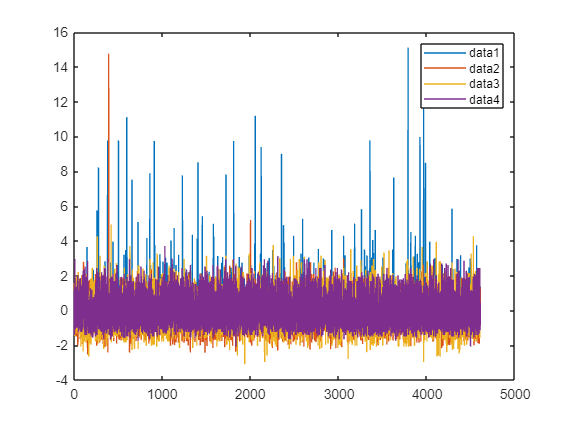

clc;
clear all;
close all;
data = readtable('updated_winequality-dataset_final_matlab.csv');

data = table2array(data);
features = normalize(data(:,1:4));
target = data(:,5);
normalized_data = [features,target];

plot(features);
legend();

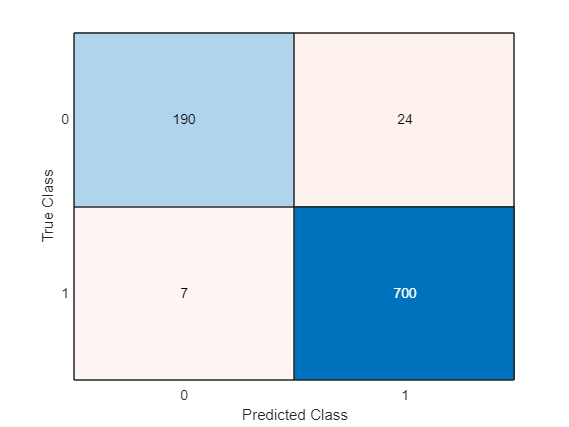


target_vec = [];
for i = 1:size(target,1)
    if(target(i) == 1)
        target_vec = [target_vec;[1,0]];
    else
        target_vec = [target_vec;[0,1]];
    end
end

[m,n] = size(data);
train_data = normalized_data(1:ceil(0.8*m),:);
test_data = normalized_data(ceil(0.8*m)+1:end,:);

[trainedClassifier, validationAccuracy] = update_GSVM_Train(train_data);
[testClassifier, test_validationAccuracy] = update_GSVM_Test(test_data);


trainedmodel =  update_GSVM_Test(train_data);
predictions = trainedmodel.predictFcn(test_data(:,1:4));
%confusionchart(test_data(:,12),predictions);
confusionchart(test_data(:,5),predictions);

ConfusionMat= confusionmat(test_data(:,5),predictions);
disp(ConfusionMat);

  Column 1

   190
     7

  Column 2

    24
   700




acc = sum(diag(ConfusionMat))/sum(sum(ConfusionMat));
disp(acc);

    0.9663

